# Project 1.2

## (a) Strong form and weak form of this model

Strong form


$$-\frac{d}{dr} (\kappa r\frac{du}{dr}) = rf,\  1<r<10$$


Since $f =0$ and $\kappa = 1.7$ under current setting, 


$$-\frac{d}{dr} (1.7 r\frac{du}{dr}) = 0, \  1<r<10$$


Weak form

By integration by parts  


$$-\kappa r \frac{du}{dr} v \big]_1^{10} + \int_1^{10} \kappa r  \frac{du}{dr} \frac{dv}{dr} dr = \int_1^{10} r f v dr$$


Since $f =0$ and $\kappa = 1.7$ under current setting, 


$$- r \frac{du}{dr} v \big]_1^{10} + \int_1^{10} r  \frac{du}{dr} \frac{dv}{dr} dr = 0$$


From $u(1) = 100, \ u(10) = 0$,


$$\int_1^{10} r  \frac{du}{dr} \frac{dv}{dr} dr = - 100 u'(1) $$


## (b) Pointwise error at $r=3.25$ cm

exact solution $u( r ) = u_o +\frac{u_i-u_o}{ln(r_o/r_i)} ln(\frac{r_o}{r})$

With $u_o = 0$, $u_i = 100$, $r_o =10$ and $r_i = 1$, the exact solution can be rewritten as

 
$$u( r ) =\frac{100}{ln(10)} ln(\frac{10}{r})$$


exact = @(r) 100/log(10)*log(10./r);

 Index of $r = 3.25$ and m stands for the mesh number

m = 4; % tried 1:4
ind = 1+2^(m-1);

Calculate error

[K,F] = Global1D();
sol = K\F;
error = abs(sol(ind)-exact(3.25))

error =      0.056216

error = 2.3102 for Mesh 1 (4 elements)

error = 0.76671 for Mesh 2 (8 elements)

error = 0.21616 for Mesth 3 (16 elements)

error = 0.056216 for Mesh 4 (32 elements)

Therefore, Mesh 4 gives the desired accuracy under 0.1 degree Celsius with 32 elements.

## (c) Plot log pointwise error VS log spacing

Since all meshes given are evenly spaced, mesh spacing $h$ can be calculated by the length of spatial domain and number of elements.

[K,F] = Global1D();
sol = K\F;
m = log2(length(sol)-1)-1; % Mesh index
ind = 1+2^(m-1);
error(m) = abs(sol(ind)-exact(3.25));
h(m) = (10-1)/(length(sol)-1);

Plot

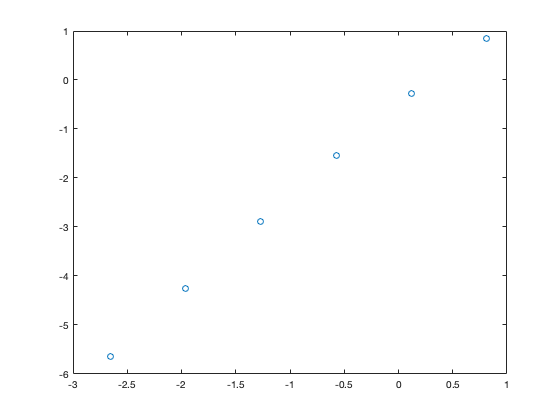

figure()
plot(log(h),log(error),'o')

Calculate the convergence rate by polyfit

coeff = polyfit(log(h),log(error),1);
slope = coeff(1)

slope =        1.8831

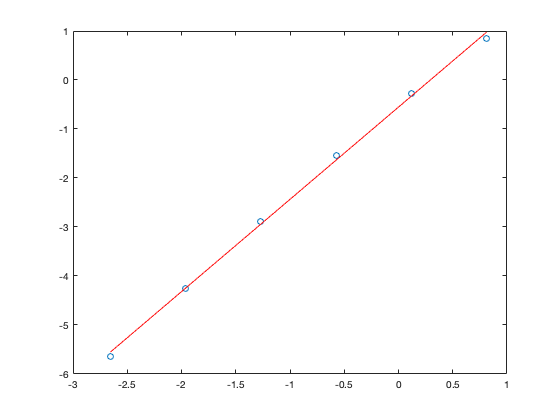

hold on
plot(log(h),polyval(coeff,log(h)),'r')

The slope of the line best fitting the points is 1.8831. Then the convergence rate of error is 1.883, close to 2.

## (d) Point error under unstructured mesh

Node index when $r=3.25$cm in unstructured mesh is $6$

[K,F] = Global1D();
sol = K\F;
perror = abs(sol(6)-exact(3.25))

perror =      0.045911

error % error in structured meshes

ans =        2.3102
      0.76671
      0.21616
     0.056216
     0.014209
    0.0035622


The point error at $r= 3.25$ cm is 0.045911. This error is close to the error of Mesh 4 (0.056216) with 32 elements. However, this unstructured mesh only has 10 elements and reached the accuracy achieved by a structure mesh with 32 elements. 

The spacing around $r=3.25$ cm is close to Mesh 4, thereby the pointwise error of these two meshes are similar. Since the spacings are different at other $r$ values, the accuracy will not be the same for every node in an unstructured mesh.

## (e) Pointwise error of $\sigma$at $r_o$ and $r_i$

kappa = 1.7;
sigma = kappa*100/log(10);
[K,F] = Global1D();
sol = K\F;
m = log2(length(sol)-1)-1; % Mesh Index
h(m) = (10-1)/(length(sol)-1);
si = -kappa*1*[sol(2)-sol(1)]/h(m);% u'(ri)
so = -kappa*10*[sol(end)-sol(end-1)]/h(m);% u'(ro)
errori(m) = abs(si-sigma)/sigma % error at ri

errori =        0.4998      0.34741      0.21528      0.12206     0.065363     0.033877


erroro(m) = abs(so-sigma)/sigma % error at ro

erroro =       0.19767     0.080445     0.034517     0.015683    0.0074367    0.0036168


Mesh 5 gives less than 10% error at $r_i$ and $r_o$.

## (g) Plot pointwise error of $\sigma$

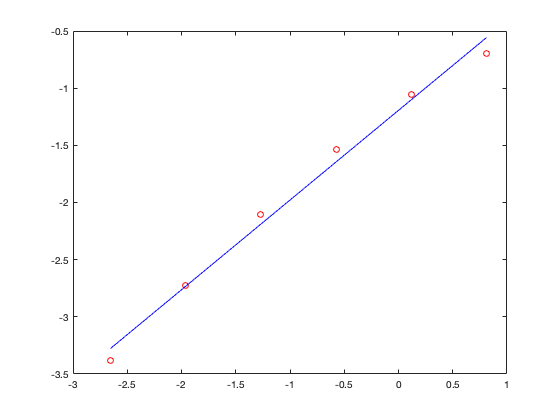

figure()
plot(log(h),log(errori),'ro')
coeffi = polyfit(log(h),log(errori),1);
hold on
plot(log(h),polyval(coeffi,log(h)),'b')

slopei = coeffi(1)

slopei =       0.78468

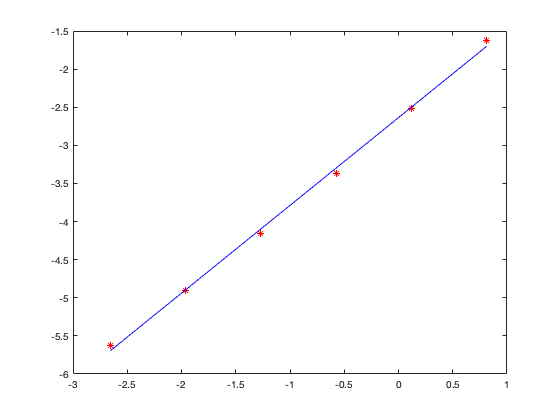


figure()
plot(log(h),log(erroro),'r*')
coeffo = polyfit(log(h),log(erroro),1);
hold on
plot(log(h),polyval(coeffo,log(h)),'b')

slopeo = coeffo(1)

slopeo =        1.1516

The rate of convergence at $r_i$ is 0.78468.

The rate of convergence at $r_o$ is 1.1516.

The rate of convergence from part (c) is 1.8, much larger than the rate of convergence of $\sigma$ at $r_i$ and $r_o$. This huge difference in rate of convergence possibly comes from the location of $r$ values. $r=3.25$cm is in the middle of spatial domain, where as $r_i$ and $r_o$ are both at the boundary. 